# Lab 8 Sessió 1

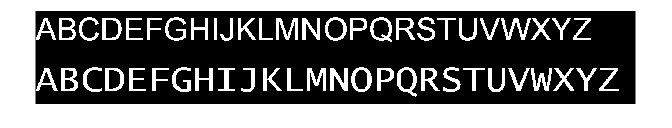

% I = imread('figures.png');
I = imread('Abecedari.png');
BW = rgb2gray(I) < 200;
imshow(BW)

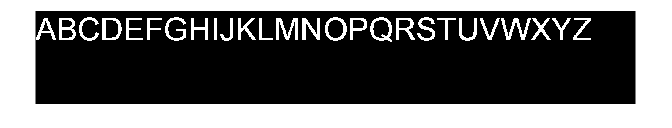


BWU = BW; BWU(end/2:end, :) = 0;

BWD = BW; BWD(1:end/2, :) = 0;
imshow(BWU);

CCU = bwconncomp(BWU);
CCD = bwconncomp(BWD);  

propsU = regionprops('table', CCU, 'Centroid', 'Solidity', 'Circularity', 'Eccentricity', 'Perimeter', 'EulerNumber', 'Orientation');
propsD = regionprops('table', CCD, 'Centroid', 'Solidity', 'Circularity', 'Eccentricity', 'Perimeter', 'EulerNumber', 'Orientation');

NumObj = CCU.NumObjects

NumObj = 26


Assig = zeros([NumObj 1]);
Assig(1:NumObj) = [1:NumObj];

FU = [propsU.EulerNumber.* propsU.Perimeter ./ propsU.Solidity];
FD = [propsD.EulerNumber .* propsD.Perimeter./ propsD.Solidity];

%FU = FU ./max(FU);
%FU = FD ./max(FD);

%Assig = dsearchn(FD,FU);

A = zeros(NumObj, NumObj);
for i = 1 : NumObj
    for j = 1 : NumObj
        A(j, i) = norm(FU(i, :) - FD(j, :));
    end
end

for k = 1 : NumObj
    [Amins, idx] = min(A);
    [Amin, Ai] = min(Amins);
    Aj = idx(Ai);
    Assig(Ai) = Aj;
    A(Aj, :) = Inf;
    A(:, Ai) = Inf;
end
%Assig = A;

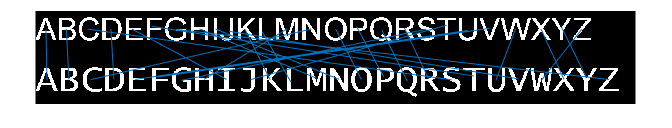

figure, imshow(BW);
hold on
for i = 1 : NumObj
    line( [propsU.Centroid(i, 1), propsD.Centroid(Assig(i), 1)], [propsU.Centroid(i, 2), propsD.Centroid(Assig(i), 2)] );
end
hold off

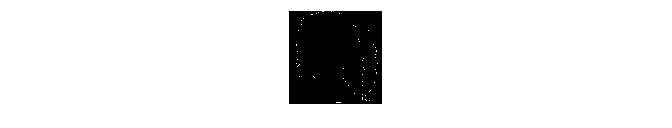

%rect = propsU.BoundingBox(26, :);
%im = BWU(rect(2)-1 : rect(2)+rect(4), rect(1)-1 : rect(1)+rect(3));
%imshow(im);

im = imread('head.png');

im = imfill(im, 'holes');
cont = xor(im, imerode(im, strel('disk', 1)));
imshow(cont);

[fila, col] = find(cont, 1);
B = bwtraceboundary(cont, [fila col], 'E'); % Perfila la figura

mig = mean(B);
Bc = B - mig;
s = Bc(:, 1) + Bc(:, 2) *1i;
z = fft(s);
ss = ifft(z);

aux = zeros(size(im));
files = round(real(ss) + mig(1));
cols = round(imag(ss) + mig(2));

aux(sub2ind(size(aux), files, cols)) = 1;
imshow(aux);

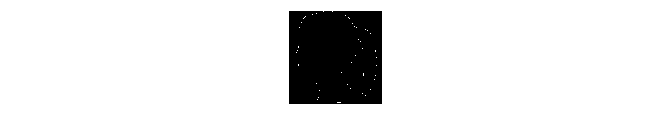




N = 30;
zz = z;
zz(N+1 : end-N) = 0;
ss30 = ifft(zz);
aux30 = zeros(size(im));
files30 = round(real(ss30) + mig(1));
cols30 = round(imag(ss30) + mig(2));

aux30(sub2ind(size(aux30), files30, cols30)) = 1;
imshow(aux30);